clear, clc, format short g


## PARTE 1

## 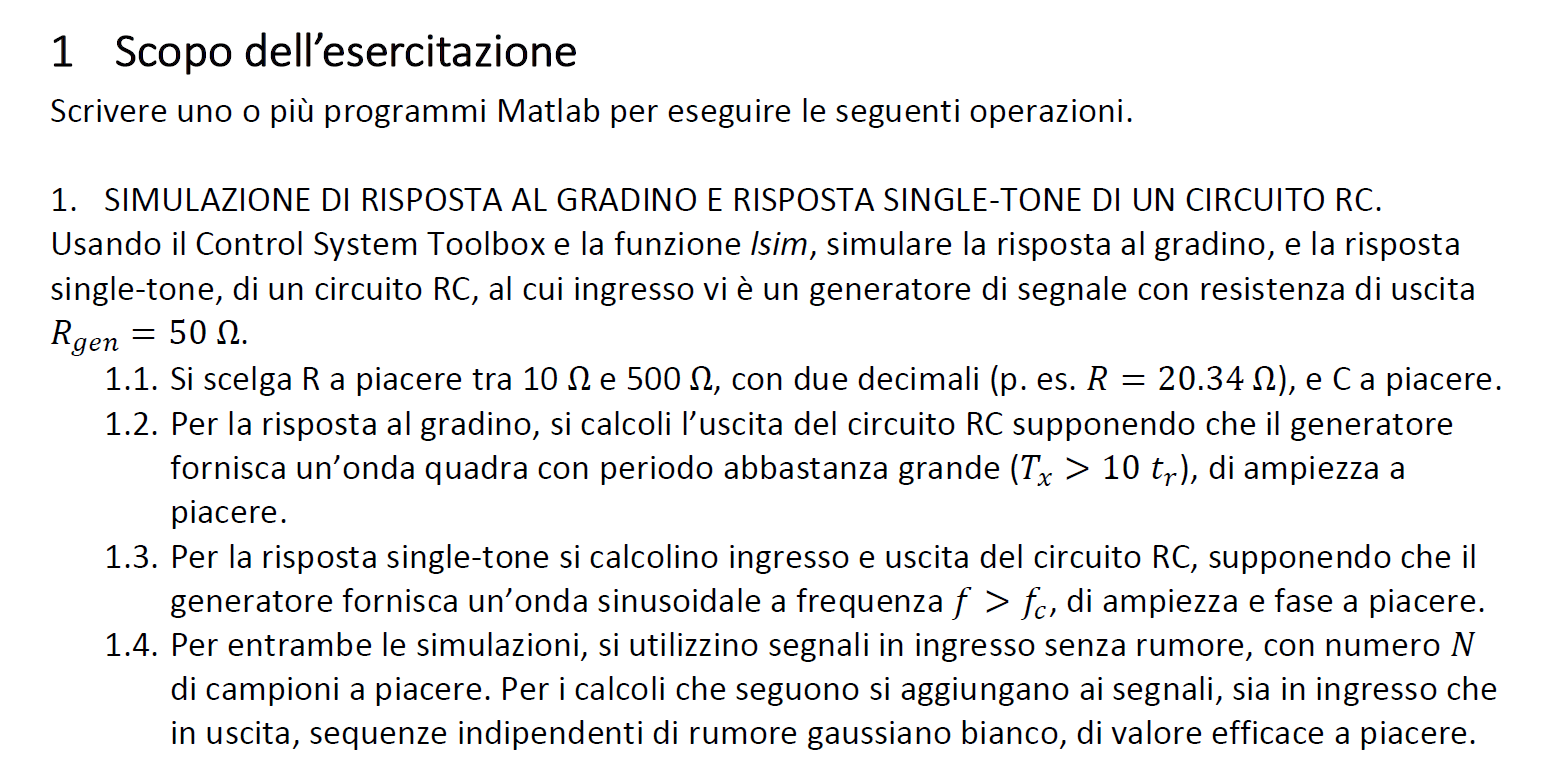


Rgen = 50;
R = 74.38;
C = 15e-9;

tr = C*(R+Rgen)*log(9)

tr =    4.0994e-06



N = 1000;

## definizione tau


tau_step = R*C;
tau_sin = (R+Rgen)*C

tau_sin =    1.8657e-06


## definizione periodi di campionamento

Td = 11*tr % durata simulazione

Td =    4.5093e-05



Ts = Td/N %periodo di campionamento

Ts =    4.5093e-08



n = (0:N-1)' %indici di campionamento

n =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



t = n*Ts % istanti di campionamento

t =             0
   4.5093e-08
   9.0186e-08
   1.3528e-07
   1.8037e-07
   2.2546e-07
   2.7056e-07
   3.1565e-07
   3.6074e-07
   4.0584e-07


## definizione onda quadra in ingresso

Vpp = 10;

x_step = Vpp*square(2*pi*t/Td)

x_step =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


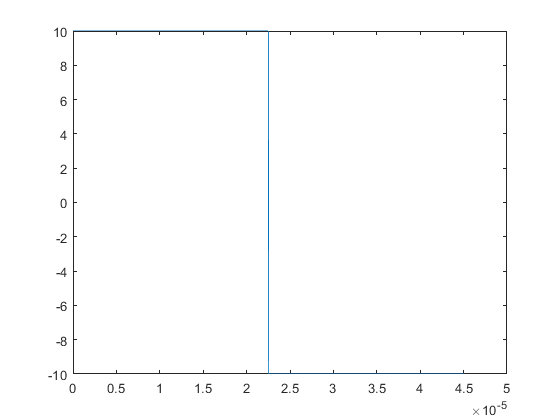


plot(t, x_step)

## definizione fdt

s = tf('s');

H1_dot = 1/(1+tau_step*s)


H1_dot =
 
         1
  ---------------
  1.116e-06 s + 1
 
Continuous-time transfer function.



## definizione risposta gradino

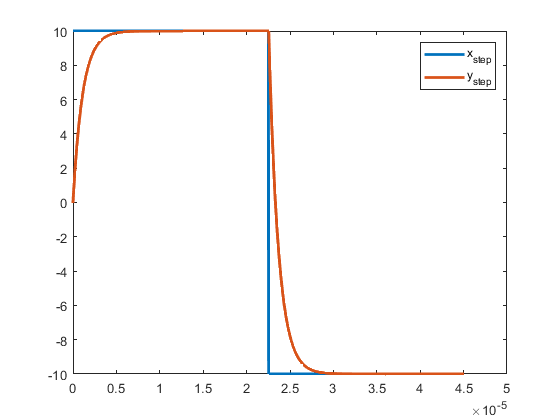

y_step = lsim(H1_dot, x_step, t);

plot(t, x_step, t, y_step, 'linewidth', 2)

legend('x_{step}', 'y_{step}')

## definizione parametri sinusoide

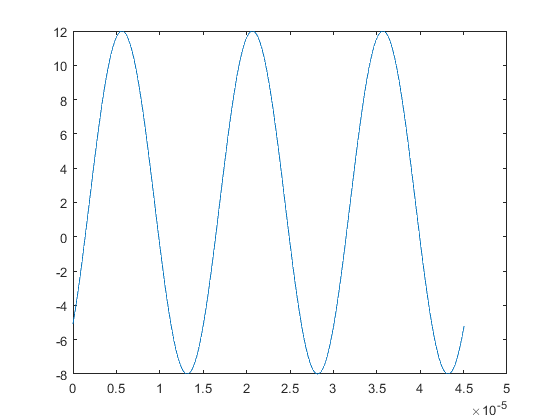

Np = 3;

Tx = Td/Np; % Durata simulazione rispetto al numero di periodi che ci interessa

fx = 1/Tx;

x_sin = 2 + Vpp*sin(2*pi*fx*t - pi/4);

plot(t, x_sin)

## definizione fdt

H_dot = 1/(1+tau_sin*s);


## definizione risposta seno

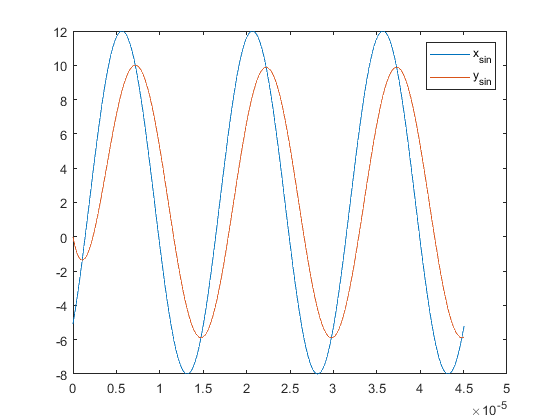

y_sin = lsim(H_dot, x_sin, t);

plot(t, x_sin, t, y_sin)

legend('x_{sin}', 'y_{sin}')

## 1.4

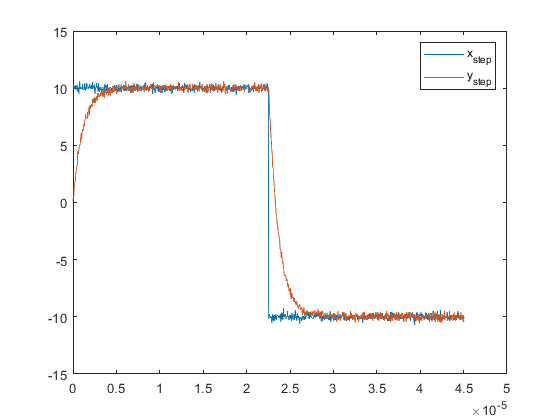

sigma = 0.2; %ampiezza del rumore
x_step = Vpp*square(2*pi*t/Td) + randn(N,1)*sigma; % segnale in ingresso con rumore AWGN

y_step = lsim(H1_dot, x_step, t) + randn(N,1)*sigma; % segnale in uscita con rumore AWGN indipendente dall'ingresso

plot(t,x_step, t, y_step)

legend('x_{step}', 'y_{step}')

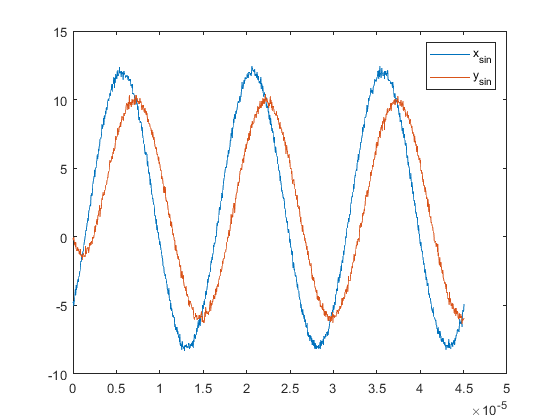


x_sin = 2 + Vpp*sin(2*pi*fx*t - pi/4) + randn(N,1)*sigma;
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;

plot(t,x_sin, t, y_sin)
legend('x_{sin}', 'y_{sin}')

## PARTE 2

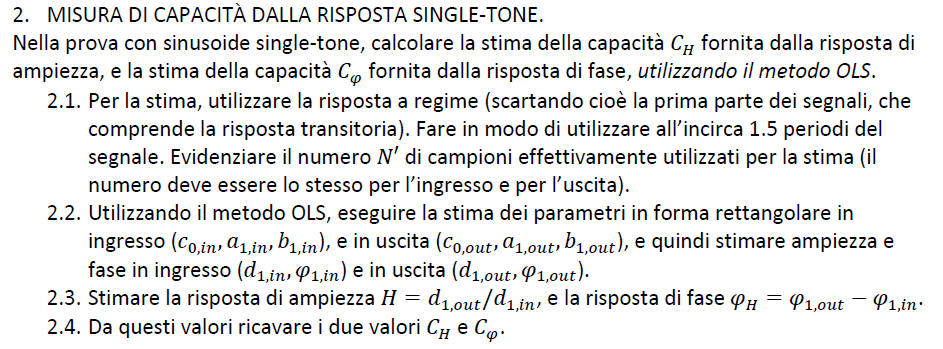

N2 = length(t)/2 % numero di campioni della risposta a regime

N2 =    500



t1 = (N2+1:N)' %vettore dei tempi contenenti gli istanti a regime

t1 =    501
   502
   503
   504
   505
   506
   507
   508
   509
   510


rng('default') % resetto il motore random

Fx = Np/N; %frequenza digitale
n = (0:N-1)'; %indici dei campioni

x_sin = 2 + Vpp*cos(2*pi*n*Fx - pi/4 - pi/2) + randn(N,1)*sigma; %trasformo seni in coseni per poter successivamente applicare il metodo OLS lineare
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;


xs = x_sin(N2+1:N) %segnale in ingresso ristretto agli ultimi campioni

xs =        9.0551
       9.1162
       8.8363
       8.7183
       8.5409
       8.4622
       8.2482
       8.6368
       7.6952
       7.4049


ys = y_sin(N2+1:N) %segnale in uscita ristretto agli ultimi campioni

ys =        9.4949
       9.8966
       9.8943
       9.7863
        9.774
       9.6072
        9.825
       9.4809
       9.4561
       9.7111


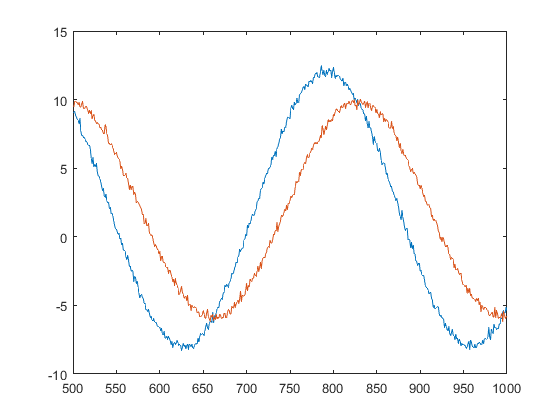



plot(t1, xs, t1, ys)


a1 = cos(-3*pi/4); % coefficienti rettangolari
b1 = sin(-3*pi/4);

wt = 2*pi*Fx*t1; % argomento delle funzioni base

A = [ones(N2,1), cos(wt), -sin(wt)] % matrice delle funzioni base

A =             1     -0.99982     0.018848
            1     -0.99929      0.03769
            1      -0.9984     0.056519
            1     -0.99716     0.075327
            1     -0.99556     0.094108
            1     -0.99361      0.11286
            1     -0.99131      0.13156
            1     -0.98865      0.15023
            1     -0.98564      0.16883
            1     -0.98229      0.18738


## Stima dei parametri di y


theta_hat_y = (A'*A)^(-1)*A'*ys; % forma alternativa A\y

%estrazione della stima dei coefficienti della forma rettangolare in uscita
c0_hat_y = theta_hat_y(1)

c0_hat_y =        1.9897


a1_hat_y= theta_hat_y(2)

a1_hat_y =       -7.8192


b1_hat_y = theta_hat_y(3)

b1_hat_y =      -0.81223



%stima dei coefficienti della forma polare in uscita

d1_hat_y = sqrt(a1_hat_y^2 + b1_hat_y^2)

d1_hat_y =        7.8613



phi1_hat_y = atan2(b1_hat_y, a1_hat_y)

phi1_hat_y =       -3.0381


## Stima dei parametri di x

theta_hat_x = (A'*A)^(-1)*A'*xs; %% A\y

%estrazione della stima dei coefficienti della forma rettangolare in
%ingresso

c0_hat_x = theta_hat_x(1)

c0_hat_x =        1.9871


a1_hat_x = theta_hat_x(2)

a1_hat_x =       -7.1883


b1_hat_x = theta_hat_x(3)

b1_hat_x =       -6.9166



%stima dei coefficienti della forma polare in ingresso

d1_hat_x = sqrt(a1_hat_x^2 + b1_hat_x^2)

d1_hat_x =        9.9755



phi1_hat_x = atan2(b1_hat_x, a1_hat_x)

phi1_hat_x =       -2.3755


## Stima risposta di ampiezza e di fase

H = d1_hat_y/d1_hat_x

H =       0.78806



phi = phi1_hat_y - phi1_hat_x

phi =      -0.66263


## Ricavo C_H e C_phi


C_H = (sqrt(1-(H^2)/H)*(1/(2*pi*fx*R)))

C_H =    1.4807e-08



C_phi = tan(-phi)*(1/(2*pi*fx*R))

C_phi =    2.5097e-08


## Parte 3

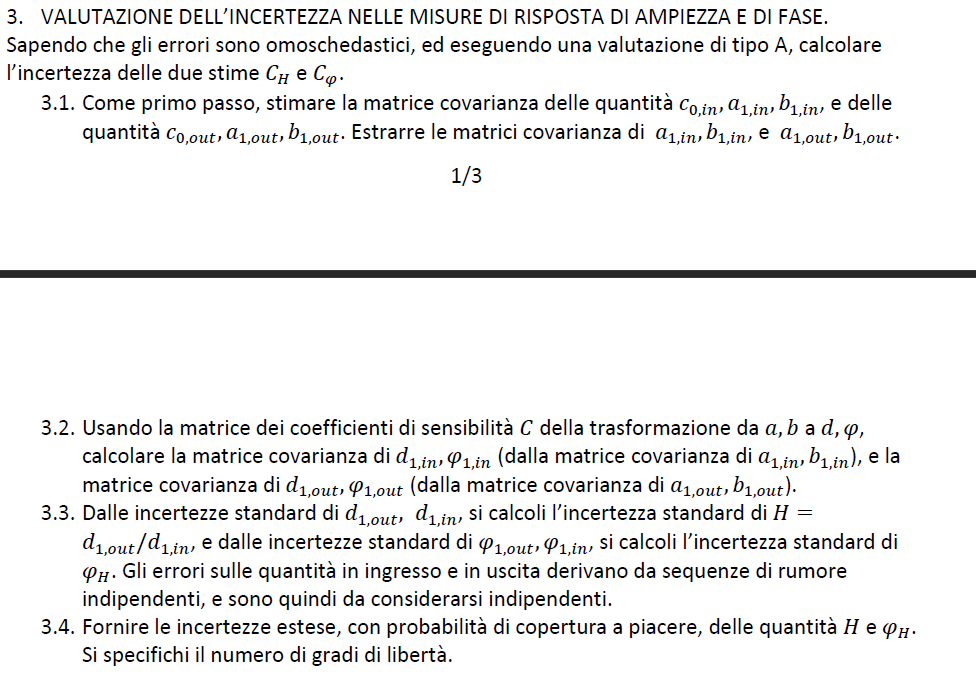

## stima con incertezza di tipo A

x_hat = A*theta_hat_x;

% stima dell'errore in ingresso
e_hat_x = ys - x_hat

e_hat_x =       0.45113
      0.98705
       1.1214
       1.1524
       1.2815
       1.2584
       1.6221
       1.4261
       1.5516
       1.9591



N_theta_x = length(theta_hat_x)

N_theta_x =      3



% Numero di gradi di libertà
nu = N-N_theta_x

nu =    997



% Stima varianzqa in ingresso con incertezza di tipo A
sigma2_x = sum(e_hat_x.^2)/nu

sigma2_x =        9.4669


## Stima matrice covarianza in ingresso sapendo che gli errori sono omoschedastici


sigma_theta_x = sigma2_x*(A'*A)^(-1)

sigma_theta_x =      0.020808  -8.3232e-05   -0.0088309
  -8.3232e-05     0.037868   3.5324e-05
   -0.0088309   3.5324e-05     0.041616



% Estrazione della matrice covarianza in ingresso riferita ai due coefficienti della
% forma rettangolare indicati
sigma_theta_x_a1_b1 = sigma_theta_x(2:end, 2:end)

sigma_theta_x_a1_b1 =      0.037868   3.5324e-05
   3.5324e-05     0.041616


## stima con incertezza di tipo A della matrice covarianza in uscita

y_hat = A*theta_hat_y;

% stima errore in uscita
e_hat_y = ys - y_hat

e_hat_y =      -0.29742
      0.12382
      0.14375
     0.060725
      0.07618
    -0.060124
      0.19086
     -0.11736
     -0.10353
       0.1928



N_theta_y = length(theta_hat_y)

N_theta_y =      3



% gradi di libertà in uscita
nu = N-N_theta_y

nu =    997



% stima varianza in uscita
sigma2_y = sum(e_hat_y.^2)/nu

sigma2_y =      0.019922



% stima matrice covarianza in uscita
sigma_theta_y = sigma2_y*(A'*A)^(-1)

sigma_theta_y =    4.3788e-05  -1.7515e-07  -1.8584e-05
  -1.7515e-07   7.9689e-05   7.4335e-08
  -1.8584e-05   7.4335e-08   8.7575e-05



%estrazione matrice covarianza riferita ai parametri della forma
%rettangolare a1 e b1
sigma_theta_y_a1_b1 = sigma_theta_y(2:end, 2:end)

sigma_theta_y_a1_b1 =    7.9689e-05   7.4335e-08
   7.4335e-08   8.7575e-05


## Passaggio dalla matrice covarianza di a1_x e b1_x a quella di d1_x e phi_x

% Calcolo simbolico matrice C_d_phi noti a1, b1 e d1
syms a1_sym b1_sym theta_sym C_sym x_sym as real

theta_sym = [(sqrt(a1_sym^2 + b1_sym^2)), atan2(b1_sym, a1_sym)]

$$theta\_sym = \left(\begin{array}{cc} \sqrt{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}} & \text{atan2}\left(b_{1,\mathrm{sym}},a_{1,\mathrm{sym}}\right) \end{array}\right)$$

x_sym = [a1_sym, b1_sym]

$$x\_sym = \left(\begin{array}{cc} a_{1,\mathrm{sym}} & b_{1,\mathrm{sym}} \end{array}\right)$$

C_sym = simplify(jacobian(theta_sym,x_sym))

$$C\_sym = \left(\begin{array}{cc} \frac{a_{1,\mathrm{sym}}}{\sqrt{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}}} & \frac{b_{1,\mathrm{sym}}}{\sqrt{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}}}\\ -\frac{b_{1,\mathrm{sym}}}{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}} & \frac{a_{1,\mathrm{sym}}}{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}} \end{array}\right)$$


C_d_phi_x = [a1_hat_x/d1_hat_x, b1_hat_x/d1_hat_x; -b1_hat_x/d1_hat_x^2, a1_hat_x/d1_hat_x^2]

C_d_phi_x =       -0.7206     -0.69335
     0.069506    -0.072237


sigma_d_phi_x = C_d_phi_x*sigma_theta_x_a1_b1*C_d_phi_x'

sigma_d_phi_x =      0.039705   0.00018783
   0.00018783   0.00039974



% estrazione incertezze standard assolute di d1 e ph in ingresso
u_d1_x = sqrt(sigma_d_phi_x(1,1))

u_d1_x =       0.19926


u_phi_x = sqrt(sigma_d_phi_x(2,2))

u_phi_x =      0.019994


## Passaggio dalla matrice covarianza di a1_y e b1_y a quella di d1_y e phi_y

C_d_phi_y = [a1_hat_y/d1_hat_y, b1_hat_y/d1_hat_y; -b1_hat_y/d1_hat_y^2, a1_hat_y/d1_hat_y^2]

C_d_phi_y =      -0.99465     -0.10332
     0.013143     -0.12652


sigma_d_phi_y = C_d_phi_y*sigma_theta_y_a1_b1*C_d_phi_y'

sigma_d_phi_y =    7.9788e-05   1.1235e-07
   1.1235e-07   1.4155e-06



% estrazione incertezze standard assolute di d1 e ph in uscita
u_d1_y = sqrt(sigma_d_phi_y(1,1))

u_d1_y =     0.0089324


u_phi_y = sqrt(sigma_d_phi_y(2,2))

u_phi_y =     0.0011897


## Calcolo incertezza standard su H e phi

H = d1_hat_y/d1_hat_x

H =       0.78806



% H è una funzione monomia, di conseguenza i coefficienti di sensibilità
% relativi sono gli esponenti delle variabili nella funzione
Cr_h = [1 -1];

% calcolo rispettive incertezze relative in uscita ed in entrata note le
% assolute estratte prima
ur_d1_y = u_d1_y/abs(d1_hat_y)

ur_d1_y =     0.0011363


ur_d1_x = u_d1_x/abs(d1_hat_x)

ur_d1_x =      0.019975



% stima incertezza relativa al quadrato, calcolata mediante propagazione, sulla misura della risposta di ampiezza H
ur_H2 = ur_d1_y^2 + ur_d1_x^2

ur_H2 =    0.00040029



% stima incertezza relativa sulla risposta in ampiezza
ur_H = sqrt(ur_H2)

ur_H =      0.020007



% stima incertezza assoluta nota la relativa ed il modulo della risposta in
% ampiezza H = d1_out/d1_in
u_H = ur_H*abs(H)

u_H =      0.015767



% calcolo risposta di fase 

phi = phi1_hat_y - phi1_hat_x

phi =      -0.66263



% essendo phi un polinomio, i coefficienti di sensibilità relativi sono i
% coefficienti del polinomio

Cr_phi = [1 -1]

Cr_phi =      1    -1



ur_phi_y = u_phi_y/abs(phi1_hat_y)

ur_phi_y =    0.00039161


ur_phi_x = u_phi_x/abs(phi1_hat_x)

ur_phi_x =     0.0084167



ur_phi2 = ur_phi_y^2 + ur_phi_x^2

ur_phi2 =    7.0995e-05



ur_phi = sqrt(ur_phi2)

ur_phi =     0.0084258



u_phi = ur_phi*abs(phi)

u_phi =     0.0055832


## Calcolo incertezze estese con cp = 95%

% dato che la valutazione dell'incertezza è di tipo A si utilizza la
% distribuzione t di Student
k = tinv((1+0.95)/2, nu)

k =        1.9623



U_H = k*u_H

U_H =       0.03094



U_phi = k*u_phi

U_phi =      0.010956



% NB: essendo N_theta molto piccolo, nu tende a N quindi K assume un valore
% molto simile a quello calcolato usando la funzione norminv nel caso di
% valutazione dell'incertezza di tipo B

## Parte 4

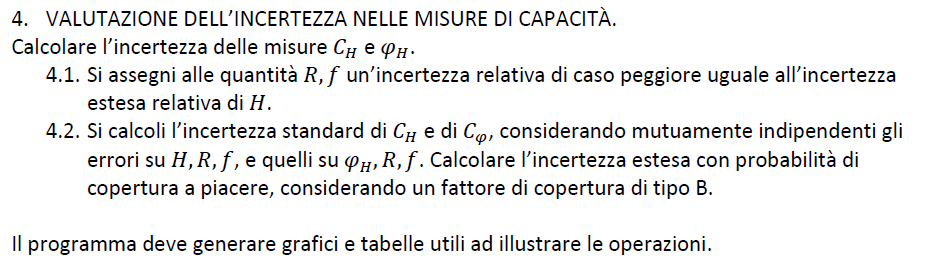

## Calcolo l'incertezza estesa relativa di C_H

% Calcolo incertezza relativa estesa sulla misura di risposta in ampiezza
Ur_H = U_H/abs(H)

Ur_H =      0.039261



% Imposto l'incertazza relativa di caso peggiore
Ur_100_R = Ur_H;
Ur_100_f = Ur_H;

% Calcolo simbolico dei coefficienti di sensibilità relativi per la mkisura
% di capacità in ampiezza

syms C_H_sym R_sym f_sym H_sym C_phi_sym phi_sym x1_sym x2_sym CrH_sym CrPhi_sym as real

% definisco la funzione di calcolo della capacità nota la risposta in
% ampiezza
C_H_sym = sqrt(1 - H_sym^2)/H_sym*(1/(2*pi*R_sym*f_sym))

$$C\_H\_sym = \frac{\sqrt{1-{H_{\mathrm{sym}}}^{2}}}{2\,H_{\mathrm{sym}}\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi }$$


% definisco il vettore degli ingressi per la misura di capacità
x1_sym = [H_sym R_sym f_sym]'

$$x1\_sym = \left(\begin{array}{c} H_{\mathrm{sym}}\\ R_{\mathrm{sym}}\\ f_{\mathrm{sym}} \end{array}\right)$$


% calcolo coefficienti di sensibiltà relativi
CrH_sym = simplify(jacobian(log(C_H_sym), x1_sym).*x1_sym')

$$CrH\_sym = \left(\begin{array}{ccc} \frac{1}{{H_{\mathrm{sym}}}^{2}-1} & -1 & -1 \end{array}\right)$$


% stima dell'incertezza standard, supponendo in ingresso distribuzione
% uniforme poiché note le incertezze di caso peggiore relative
ur_f = Ur_100_f/sqrt(3)

ur_f =      0.022668


ur_R = Ur_100_R/sqrt(3)

ur_R =      0.022668



% calcolo pratico, sostituendo ai valori simbolici i valori noti, calcolati
% precedentemente
CrH = [(1/(H^2 - 1)) -1 -1]

CrH =       -2.6388           -1           -1



ur_C_H = [ur_H ur_R ur_f]

ur_C_H =      0.020007     0.022668     0.022668



% stima matrice covarianza relativa in ingresso per la misura della
% capacità con risposta in ampiezza
sigmar_C_H_input = diag(ur_C_H.^2)

sigmar_C_H_input =    0.00040029            0            0
            0   0.00051382            0
            0            0   0.00051382



% stima matrice covarianza relativa in uscita
sigmar_C_H_output = CrH*sigmar_C_H_input*CrH'

sigmar_C_H_output =      0.003815



% stima incertezza standard in uscita
ur_CH = sqrt(diag(sigmar_C_H_output))

ur_CH =      0.061766



% stima incertezza assoluta della misura di capacità in uscita, noti
% l'incertezza relativa in uscita ed il modulo della capacità
u_CH = ur_CH * abs(C_H)

u_CH =    9.1454e-10


## Calcolo dell'incertezza relativa di C_phi

% calcolo simbolico coefficienti relativi della misura di capacità nota la
% risposta di fase
C_phi_sym = tan(-phi_sym)*(1/(2*pi*R_sym*f_sym))

$$C\_phi\_sym = -\frac{\tan\left(\varphi_{\mathrm{sym}}\right)}{2\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi }$$


x2_sym = [phi_sym R_sym f_sym]'

$$x2\_sym = \left(\begin{array}{c} \varphi_{\mathrm{sym}}\\ R_{\mathrm{sym}}\\ f_{\mathrm{sym}} \end{array}\right)$$


CrPhi_sym = simplify(jacobian(log(C_phi_sym), x2_sym).*x2_sym')

$$CrPhi\_sym = \left(\begin{array}{ccc} \frac{2\,\varphi_{\mathrm{sym}}}{\sin\left(2\,\varphi_{\mathrm{sym}}\right)} & -1 & -1 \end{array}\right)$$


%double(subs(CrPhi_sym,x2_sym,[phi R fx]))

% sostituisco le relazioni ottenute col calcolo simbolico usando le
% variabili calcolate prima
CrPhi = [(2*phi/sin(2*phi)) -1 -1]

CrPhi =        1.3662           -1           -1



ur_C_Phi = [ur_phi ur_R ur_f]

ur_C_Phi =     0.0084258     0.022668     0.022668



% stima matrice covarianza relativa in ingresso
sigmar_C_Phi_input = diag(ur_C_Phi.^2)

sigmar_C_Phi_input =    7.0995e-05            0            0
            0   0.00051382            0
            0            0   0.00051382



% stima matrice covarianza relativa in uscita
sigmar_C_Phi_output = CrPhi*sigmar_C_Phi_input*CrPhi'

sigmar_C_Phi_output =     0.0011602



ur_CPhi = sqrt(diag(sigmar_C_Phi_output))

ur_CPhi =      0.034061



% calcolo incertezza relativa in uscita note la misura di capacità e
% l'incertezza relativa sulla misura ottenuta dalla risposta di fase
u_CPhi = ur_CPhi * abs(C_phi)

u_CPhi =    8.5484e-10


## Calcolo incertezze estese con cp = 90%

% stima incertezze estese con valutazioe di tipo B (dunque usando norminv)
k = norminv((1+0.9)/2)

k =        1.6449



U_90_C_H = k*u_CH

U_90_C_H =    1.5043e-09



U_90_C_Phi = k*u_CPhi

U_90_C_Phi =    1.4061e-09
